# Industrial cutter - anomaly detection

#### Autoencoder-based anomaly detection

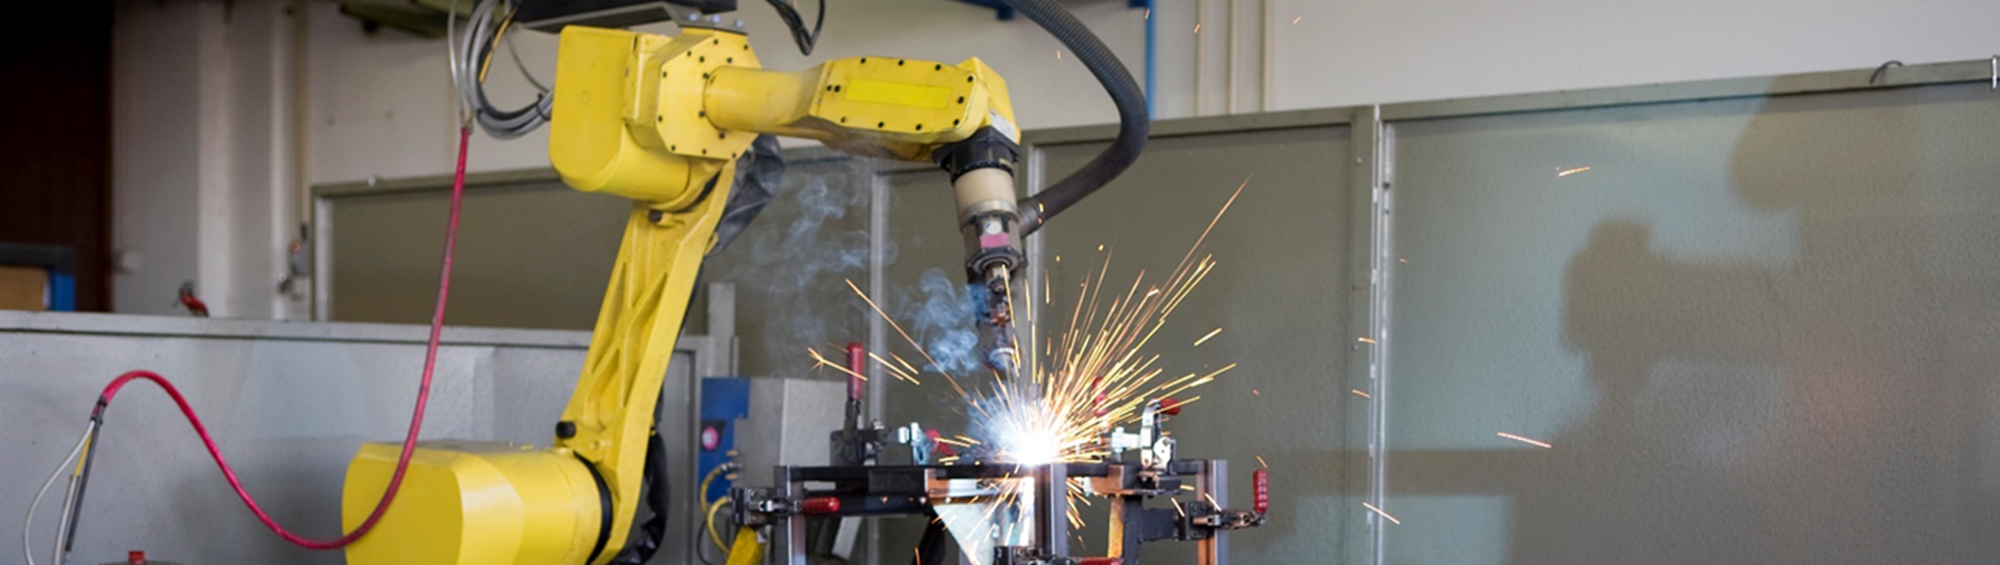

Here is an example where a Deep Learning Autoencoder is trained to detect if a machine metal cutter is working normally or abnormally. It is trained on a set of 12 features, extracted from historical accelerometer data from "normal" operation, which was the time directly after a scheduled maintenance period. Features include mean, standard deviation, kurtosis, crest factor, and were computed from raw data using the [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html) from the [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html).

This trained model is then used to monitor the machine over time. At a certain point the model output differs and drifts from the sensor data output. The more drift, the larger the amount of anomalies are detected which is an indication the machine is acting abnormal.

**Load Historical Features & Labelled State**

The data has 2 labelled states **Before** & **After**. These refer too data collected before and after maintenance.

clear all;
load FeatureEntire.mat
idx = isinf(feature_All.("ch3_stats/Col1_THD"));
feature_All(idx, :) = [];

feature_All

feature_All = 17642×13 table
    label     ch1_stats/Col1_CrestFactor    ch1_stats/Col1_Kurtosis    ch1_stats/Col1_RMS    ch1_stats/Col1_Std    ch2_stats/Col1_Mean    ch2_stats/Col1_RMS    ch2_stats/Col1_Skewness    ch2_stats/Col1_Std    ch3_stats/Col1_CrestFactor    ch3_stats/Col1_SINAD    ch3_stats/Col1_SNR    ch3_stats/Col1_THD
    ______    __________________________    _______________________    __________________    __________________    ___________________    __________________    _______________________    __________________    __________________________    ____________________

**Split into Training & Validation Datasets**

idx = cvpartition(feature_All.label, 'holdout', 0.1);
feature_train = feature_All(idx.training, :);
feature_val = feature_All(idx.test, :);

**Model Training**

The model is going to be trained on data **After** maintenance. This is the time when the machine is running "normally".

doTraining = false; % Select if you would like the model to train or use the pretrained model on file

% Select data with label After
Xtemp = feature_train{feature_train.label=='After', 2:end};

% Arrange data into cells
for i = 1:length(Xtemp)
    X{i,:} = Xtemp(i,:);
end

% Define biLSTM network layers
layers = [ sequenceInputLayer(1, 'Name', 'in')
    bilstmLayer(16, 'Name', 'bilstm1')
    reluLayer('Name', 'relu1')
    bilstmLayer(32, 'Name', 'bilstm2')
    reluLayer('Name', 'relu2')
    bilstmLayer(16, 'Name', 'bilstm3')
    reluLayer('Name', 'relu3')
    fullyConnectedLayer(1, 'Name', 'fc')
    regressionLayer('Name', 'out') ];

% Set Training Options
options = trainingOptions('adam', ...
    'Plots', 'training-progress', ...
    'MiniBatchSize', 500,...
    'MaxEpochs',500);

if doTraining == true
    net = trainNetwork(X, X, layers, options);
else
    load TrainedModel
end




**Visualize Model Behavior on Validation Data**

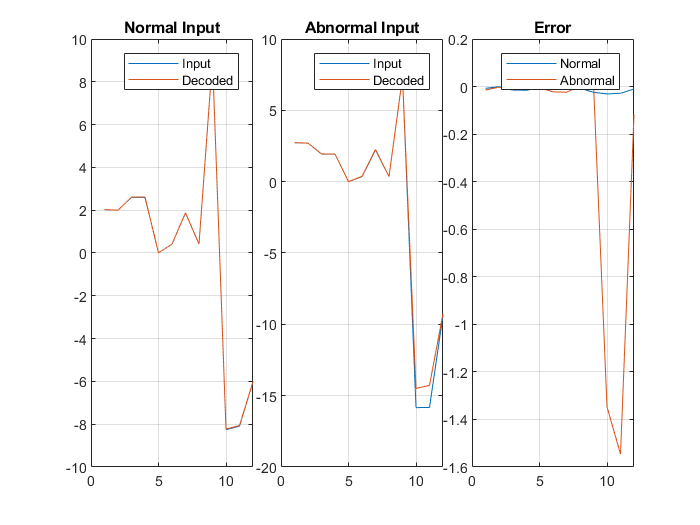

% Extract a sample from Normal(After) and Abnormal(Before)
testNorm = {feature_val{1200, 2:end}}; % 1200 is a sample from After
testAbNorm = {feature_val{200, 2:end}}; % 200 is a sample from Before

% Predict decoded signal for both
decodedNorm = predict(net,testNorm);
decodedAbNorm = predict(net,testAbNorm);

% Visualize
tiledlayout(1, 3,'TileSpacing','none')
nexttile
plot(testNorm{:}), title('Normal Input'), hold on, plot(decodedNorm{:}), hold off, legend({'Input', 'Decoded'}), grid on
nexttile
plot(testAbNorm{:}),title('Abnormal Input'), hold on, plot(decodedAbNorm{:}), hold off, legend({'Input', 'Decoded'}), grid on
nexttile
plot(testNorm{:} - decodedNorm{:}), title('Error'), hold on, plot(testAbNorm{:} - decodedAbNorm{:}), hold off, legend({'Normal', 'Abnormal'}), grid on

**Visualize Model Error on Validation Data**

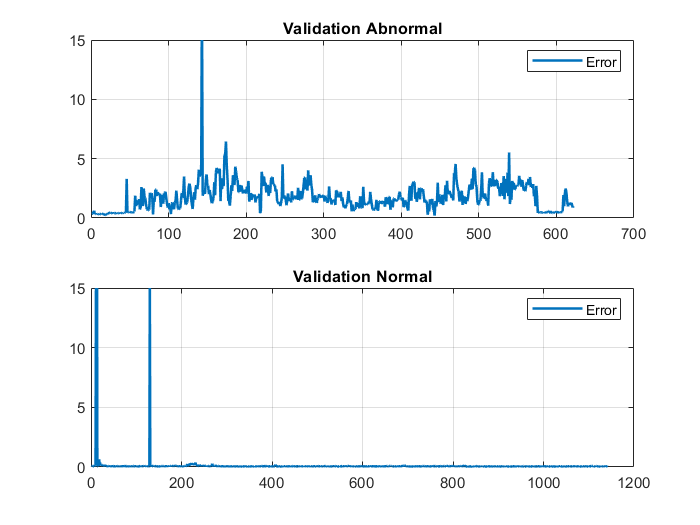

% Extract data Before maintenance
tmp_val = feature_val{feature_val.label=='Before', 2:end};

% Arrange data into cells
for i = 1:length(tmp_val)
    Xtmp_val{i,:} = tmp_val(i,:);
end

% Predict output before maintenance
y_hat = predict(net, Xtmp_val);

% Calculate error (predicted-actual)
for i = 1:length(tmp_val)
    E1(i,:) = sqrt(sum((y_hat{i} - Xtmp_val{i}).^2));
end

% Plot results
subplot(211), plot(1:length(E1), E1, 'LineWidth',1.5), legend('Error')
grid on, ylim([0 15]), title('Validation Abnormal')

% Extract data After maintenance
tmp_val2 = feature_val{feature_val.label=='After', 2:end};

% Arrange data into cells
for i = 1:length(tmp_val2)
    Xtmp_val2{i,:} = tmp_val2(i,:);
end

% Predict output after maintenance
y_hat2 = predict(net, Xtmp_val2);

% Calculate error (predicted-actual)
for i = 1:length(tmp_val2)
    E2(i,:) = sqrt(sum((y_hat2{i} - Xtmp_val2{i}).^2));
end

% Plot results
subplot(212), plot(1:length(E2), E2, 'LineWidth',1.5), legend('Error')
grid on, ylim([0 15]), title('Validation Normal')

**Validation Accuracy**

fprintf('Mean Error value for Abnormal dataset : %.2f\n', mean(E1))

Mean Error value for Abnormal dataset : 1.80


fprintf('Mean Error value for Normal dataset : %.2f', mean(E2))

Mean Error value for Normal dataset : 0.12

**Accuracy for entire validation dataset**

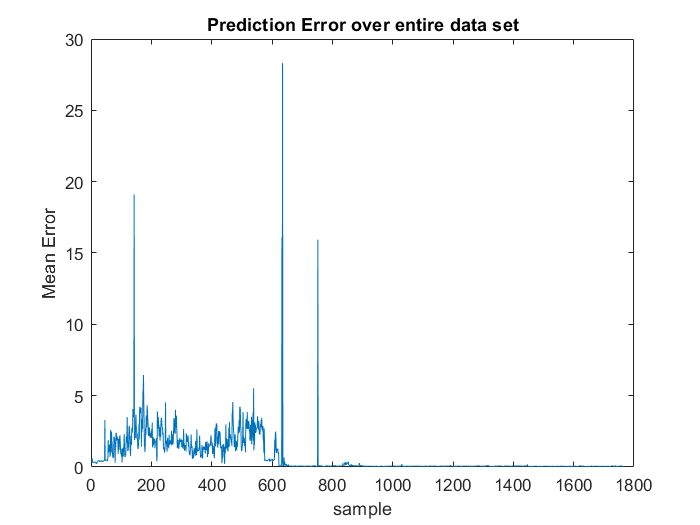

tmp_all = feature_val{:, 2:end};
for i = 1:length(tmp_all)
    Xtmp_val3{i,:} = tmp_all(i,:);
end
y_hat3 = predict(net, Xtmp_val3);
for i = 1:length(tmp_all)
    E3(i,:) = sqrt(sum((y_hat3{i} - Xtmp_val3{i}).^2));
end

figure;
plot(E3)
title('Prediction Error over entire data set')
ylabel('Mean Error')
xlabel('sample')

% Threshold for detecting abnormalities 
predAE = E3'>0.3;

% Accuracy of the anomaly detection autoencoder
predAE = categorical(predAE, [1, 0], {'Before', 'After'})';
acc = numel(find(feature_val.label == predAE))/length(predAE)*100;
fprintf('Mean accuracy for Entire dataset : %.2f\n', mean(acc))

Mean accuracy for Entire dataset : 99.04
